**Part 2:** Produce 2D arrays of the specified function(s) via the specified method(s) and produce appropriate graph(s) *in another figure*.

Generate these functions:

- 
$$\exp \left(-x^2 -y^2 \right)$$


- $\cos \left(3\theta \right)\left(r-r^3 \right)\;\exp \left(-r^2 \right)$, where $\left(r,\theta \right)$are polar coordinates but plot in (x,y) space 

- HINT: you may use [atan2 (Links to an external site.)](https://au.mathworks.com/help/matlab/ref/atan2.html) or [angle. (Links to an external site.)](https://au.mathworks.com/help/matlab/ref/angle.html)

Demonstrate these methods at least once each:

- nested loops

- meshgrid *or* broadcasting

Show these plots once each:

- A top-down plot

- A 3D plot

Make sure that all plots are carefully presented to allow a full understanding of the results.

clc;
clear;

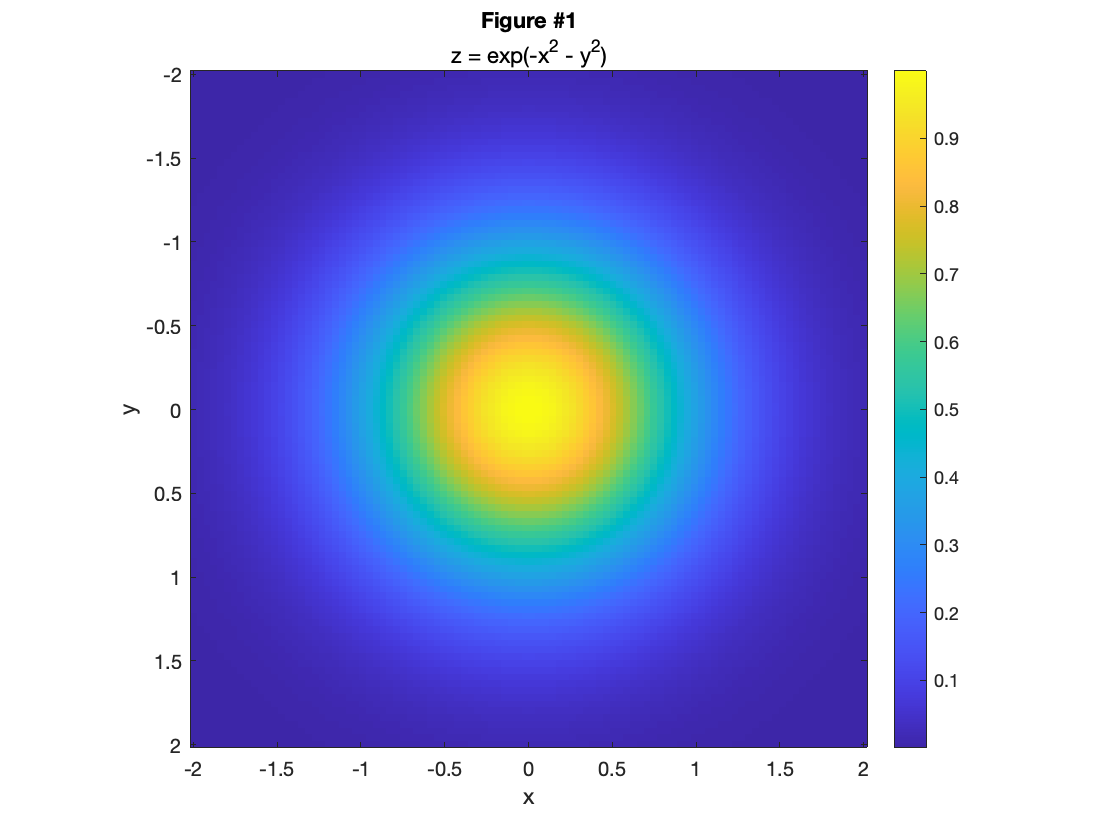

% Broadcasting and top-down plot
x = linspace(-2, 2);
y = linspace(-2, 2).';
z = exp(-x.^2 - y.^2); % broadcasting

% Plot data
imagesc(x, y, z);

% Decorate Figure #1
colorbar
axis('image')
subtitle('z = exp(-x^2 - y^2)')
xlabel('x')
ylabel('y')
title('Figure #1')

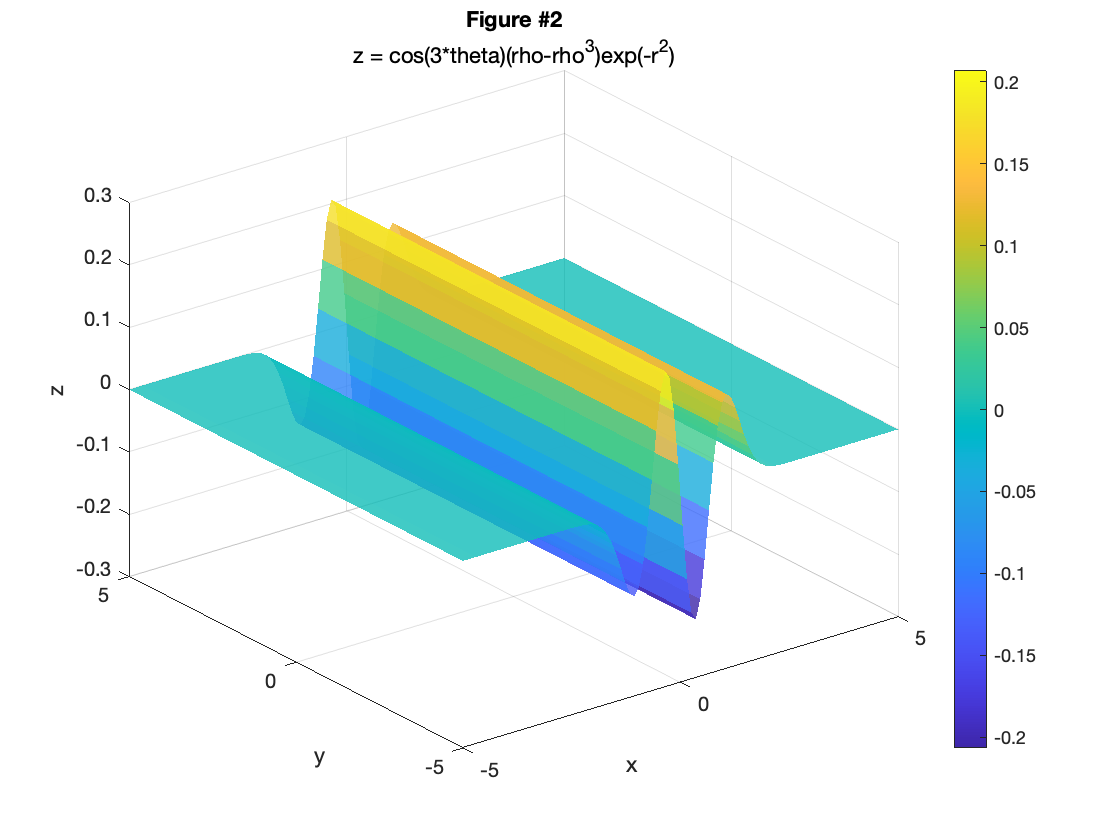

% Generate domain in Cartesian coordinates
x2 = linspace(-5, 5);
y2 = linspace(-5, 5);

% Generate matrix of matching size to store z values (for rendering)
zMatrix = nan([length(x2), length(y2)]);

for i = 1:length(x2)
    % Grab the corresponding x and y coordinates each loop
    xVal = x2(:, i);
    yVal = y2(:, i);

    % Convert the Cartesian coordinate into a Polar coordinate
    rhoVal = sqrt((xVal .^ 2) + (yVal .^ 2));
    thetaVal = atan2(yVal, xVal);

    % Use Polar coordinate as parameters to compute the given function
    % and store result of function into each row of matrix zMatrix
    zMatrix(:, i) = cos(3 .* thetaVal) .* (rhoVal - rhoVal .^ 3) .* exp(-rhoVal .^ 2);
end

% Plot cartesian coordinates
surf(x2, y2, zMatrix, 'EdgeColor', 'none', 'FaceAlpha', 0.8);

% Decorate Figure #2
colorbar
title('Figure #2')
subtitle('z = cos(3*theta)(rho-rho^3)exp(-r^2)');
xlabel('x');
ylabel('y');
zlabel('z');